# Assignment #2: ECMS

**Read the following instructions carefully. **

This live script serves as a template for your second assignment. You must replace all the text in the template with your own report, filling in each section as appropriate. Remove these instructions from your final report as well.

Consider the empty code sections as a guideline: you can add more or remove them. However, please note that all local function definitions (such as the function for your torque controller) must be declared at the end of the live script, or they won't work.

In order to get your assignment graded, you must upload the following files:

- Your assignment livescript in .mlx format

- Your assignment in pdf format.

- Your results in a .mat file

- Any other function/file needed to run this live script.

You must compress all these files in a .zip folder. You must name the folder "group" + [your group number with double digits], e.g. "group01.zip", "group12.zip". Make sure you dont type "group1".

Upload all files in the *Assignment 02* activity on the course's Moodle website, which you can access from the *Portale della Didattica*. Only one person for each group should upload the folder; please avoid multiple uploads of the same assignment.

**Grading**

For this report, you will evaluated based on the following criteria:

- Whether the controller and bisection algorithm work as intended or not.

- Your description and explanation, in plain text, of your implementation of the ecms controller and of the bisection algorithm.

- Your analysis of the controller's performance, supported by the appropriate plots and results. You should at least use the post-processing tools we provided to you; if you find them inadequate, you can develop your own or modify them to illustrate additional information.

- The quality of the code. This includes general code readability, approriate usage of clear and succint code comments, usage of meaningful and unambiguous variable names, etc.

## Group information

Group number: 09

Students:

- Ulugbek Rakhmatullaev, s330568

- Nozima Yakubova, s344733

- Nicolo Ferruggia, s349151

## Load the cycle and vehicle data

Load data and other preliminaries. Remember to scale the vehicle data.

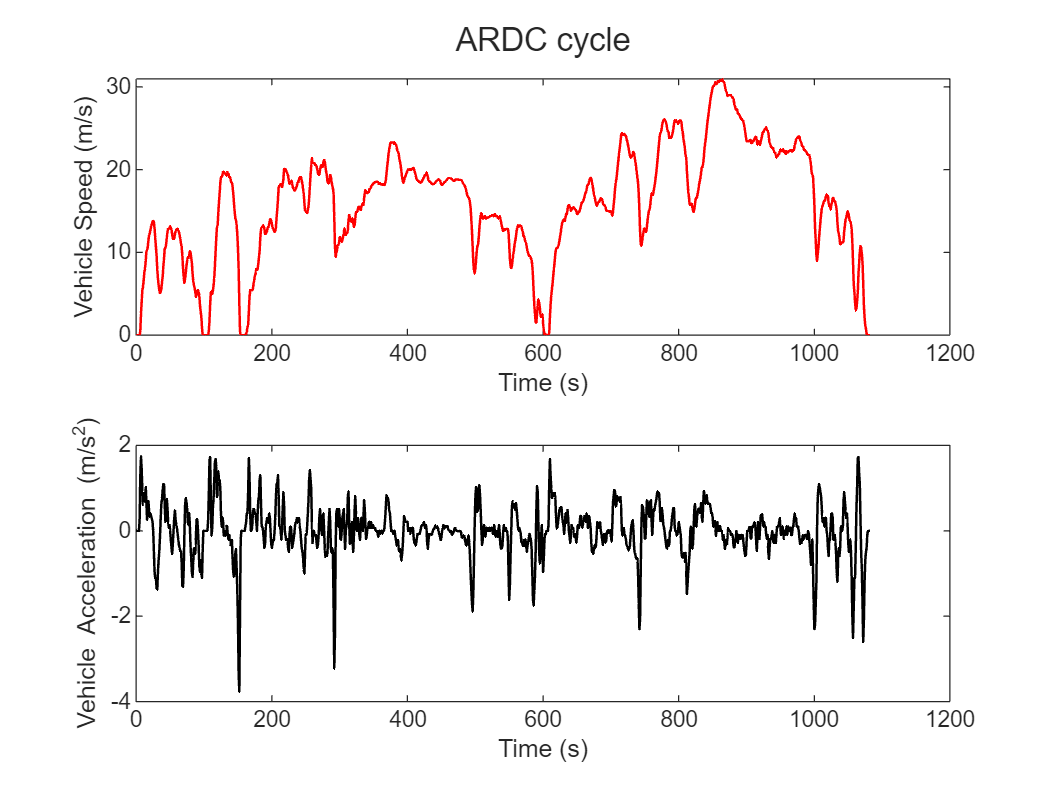

clc; clear; close all; % Housekeeping

% Add the folders to Path
addpath("utilities");
addpath("models");
addpath("data");

mission = load("ARDC.mat");         % Load the ARDC cycle
time = mission.time_s;              % [s]
vehSpd = mission.speed_km_h./3.6;   % [m/s]
vehAcc = mission.acceleration_m_s2; % [m/s^2]

% Create the figure of ARDC cycle
t = tiledlayout(2,1); 

nexttile(1)
% Plot the vehicle speed
plot(time,vehSpd, LineStyle="-", LineWidth=1, Color='r');
xlabel("Time (s)");
ylabel("Vehicle Speed (m/s)");

nexttile(2)
% Plot the vehicle acceleration
plot(time, vehAcc, LineStyle="-", Color='k', LineWidth=1);
xlabel("Time (s)");
ylabel("Vehicle Acceleration (m/s^2)");
title(t, "ARDC cycle");

veh = load("data\vehData.mat");
SOC(1) = 0.6;
s = 2.652;

% Scale vehicle data according to the group parameters
motPwr = 70000; % [W]
engPwr = 66000;  % [W]
battEnrg = 1260;  % [Wh]
veh = scaleVehData(veh, motPwr, engPwr, battEnrg);

a = 2.6;
psiA = run_simulation(a, time, vehSpd, vehAcc, veh) % Simulation with eqFactor = a, when deltaSOC is negative

psiA = -0.1383

b = 2.7;
psiB = run_simulation(b, time, vehSpd, vehAcc, veh) % Simulation with eqFactor = b, when deltaSOC is positive

psiB = 0.2572

## Equivalence factor calibration

Develop a bisection algorithm to calibrate the equivalence factor in order to ensure charge-sustaining operation. The terminal SOC deviation should be within 0.01, i.e. your terminal SOC should be $0.59 < \sigma_\mathrm{f} <0.61$.

Describe your calibration algorithm, by using code comments and/or this text section. **You will not get full marks if your function is not documented appropriately.**

function s_opt = bisectionAlgorithm(vehSpd, vehAcc, time, veh)

s_opt = 2.6375

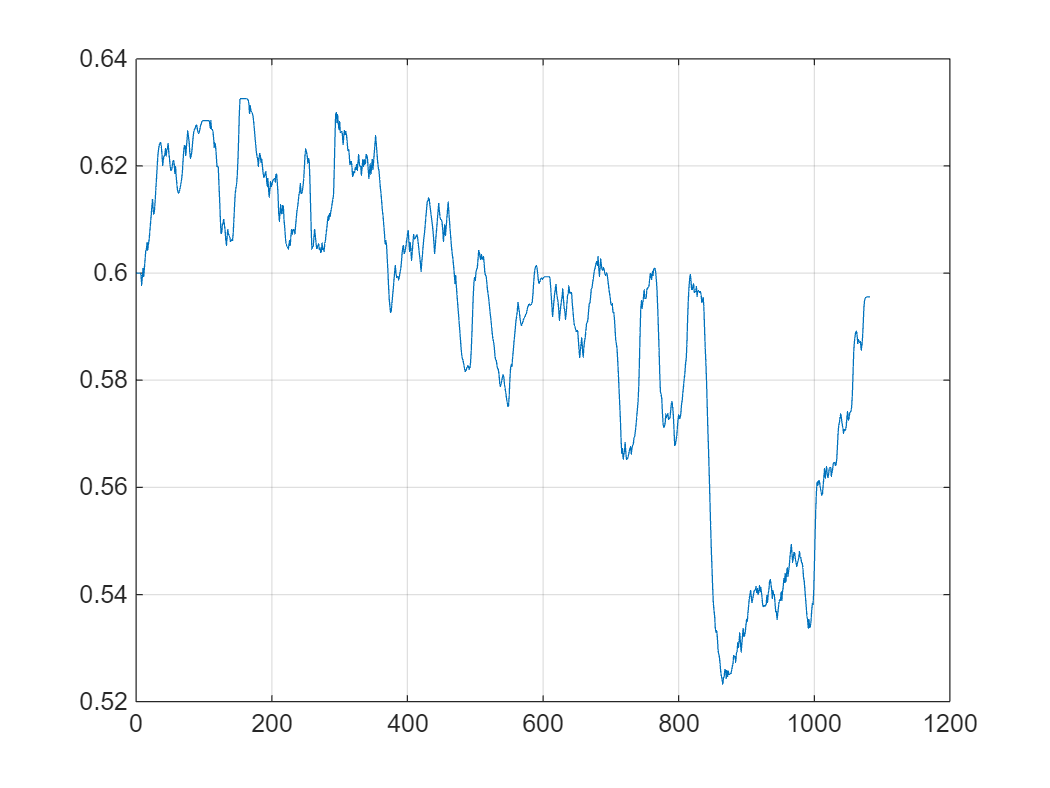

tol = 0.005;
a = 2.6;
b = 2.7;
while true
    s = (a + b) / 2;
    psiC = run_simulation(s, time, vehSpd, vehAcc, veh);
    if abs(psiC) < tol
        s_opt = s;
        break
    else

        if psiC > 0
            b = s;
        elseif psiC < 0
            a = s;
        end
    end
end
end

## Run a simulation with the calibrated equivalence factor

Run a simulation with the calibrated equivalence factor, so you can inspect the behavior of the charge-sustaining ECMS controller.

s_opt = bisectionAlgorithm(vehSpd, vehAcc, time, veh)

for n = 1:length(time)
    [engSpd(n), engTrq(n)] = ecmsControl(SOC(n), vehSpd(n), vehAcc(n), s_opt, veh);
    [SOC(n+1), stageCost(n), unfeas(n), prof(n)] = ...
        hev_model(SOC(n), [engSpd(n), engTrq(n)], [vehSpd(n), vehAcc(n)], veh);
end

figure

Fuel consumption: 0.51 kg


plot(time, SOC(1:1083));

Fuel economy: 3.75 l/100km


grid on

Final SOC: 0.596


## Save results

Save the time profiles, fuel consumption (in kg), fuel economy (in l/100km), final SOC and calibrated equivalence factor in a mat-file named `results.mat`. Make sure they are named exactly as in the following code section.

If you have not done it before, use this code to convert your time profiles into scalar structures and pack them into a parent structure:

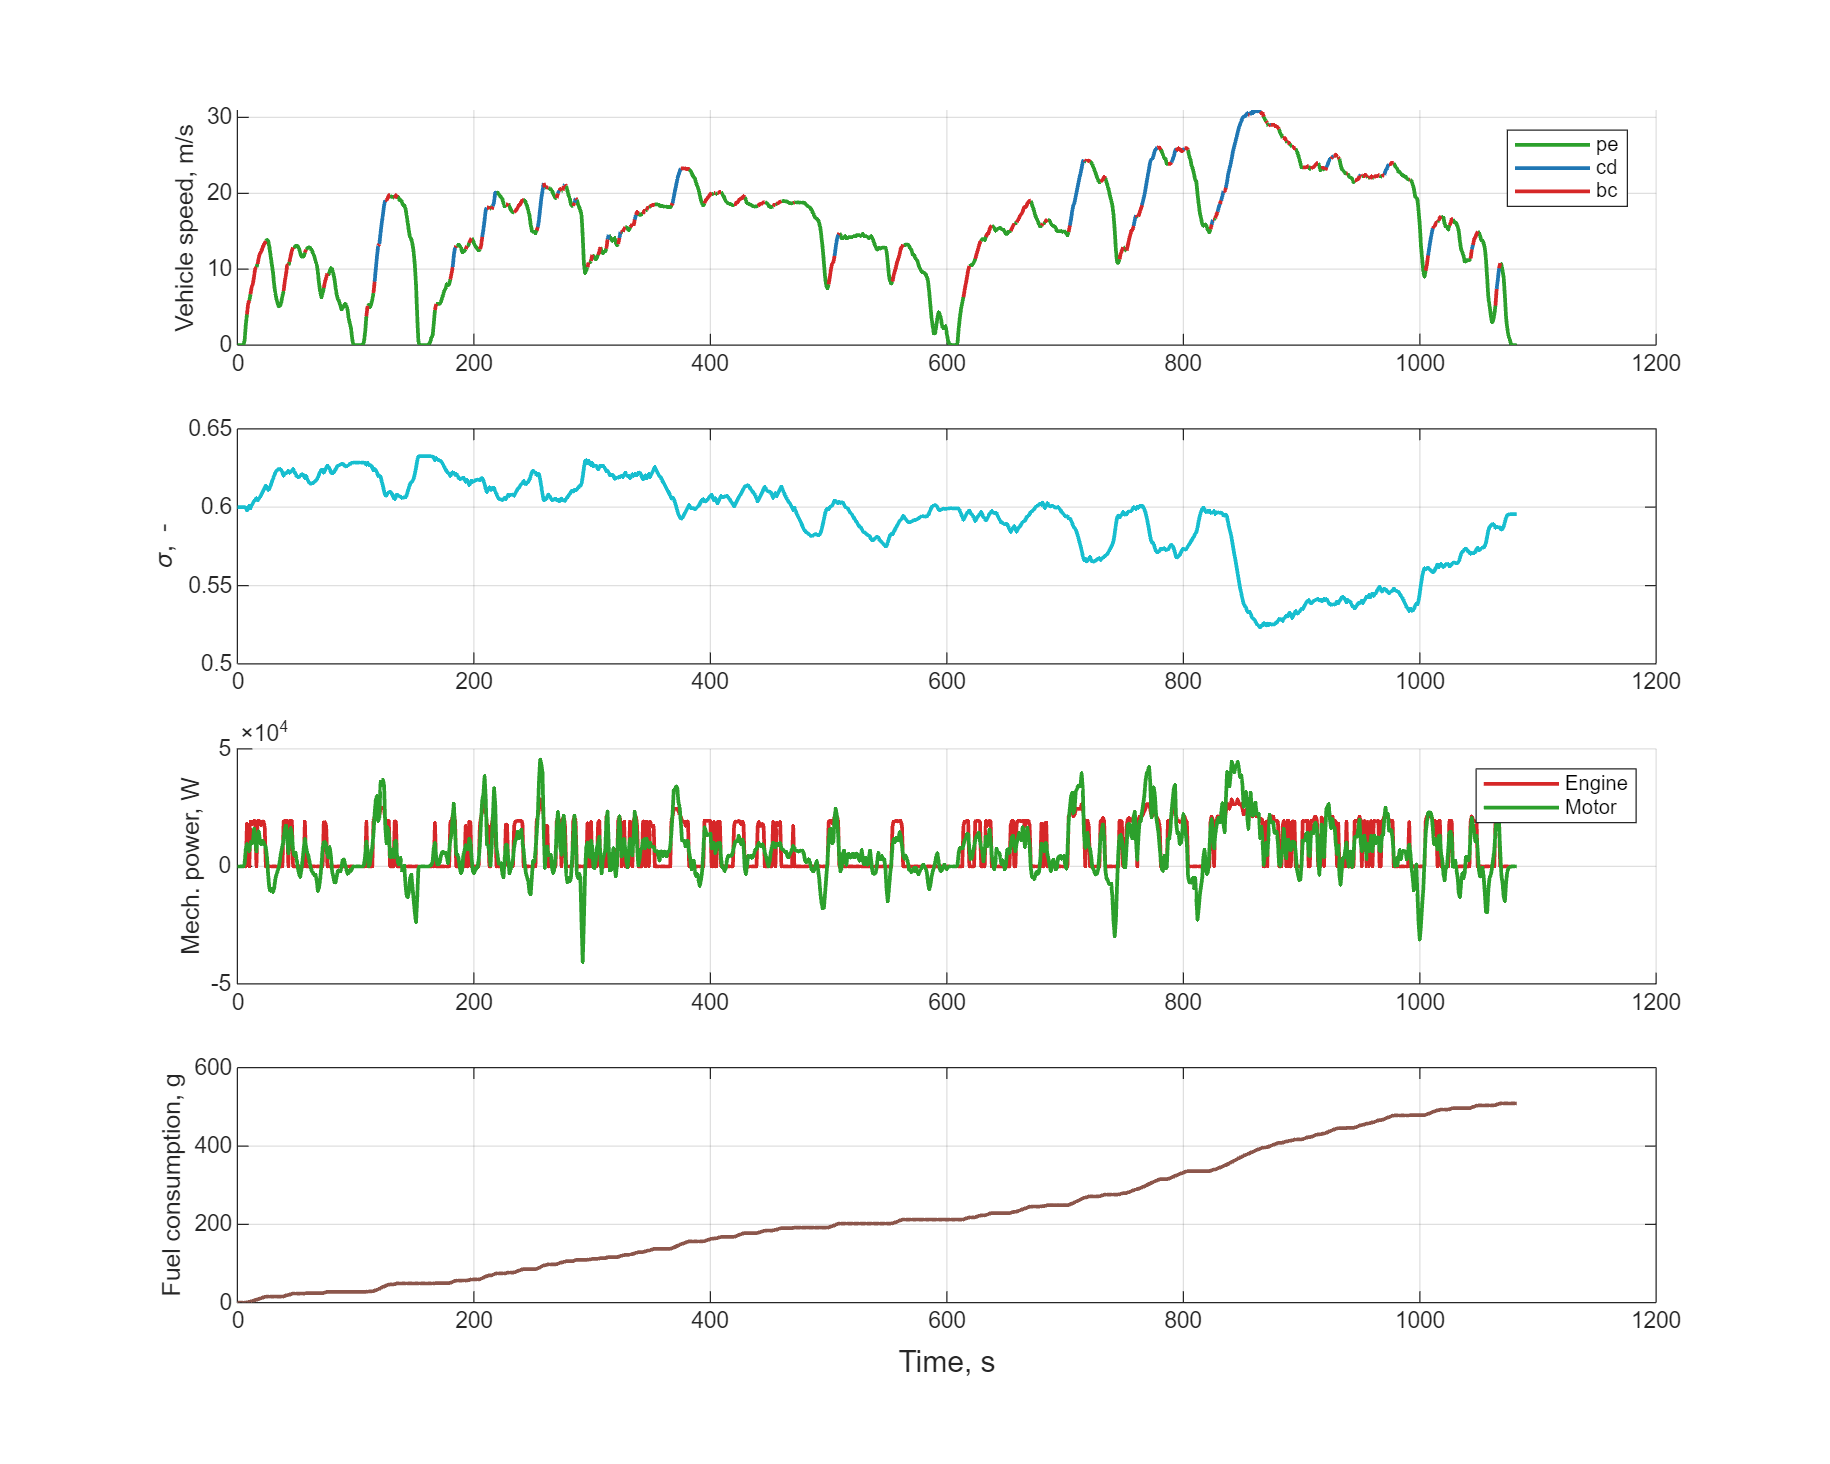

% Transform the non-scalar struct containing time profiles into scalar
% structs; this makes their manipulation easier.

prof = structArray2struct(prof);
% Compute total fuel consumption in kg
fuelConsumption = sum(prof.fuelFlwRate) * 1e-3; 


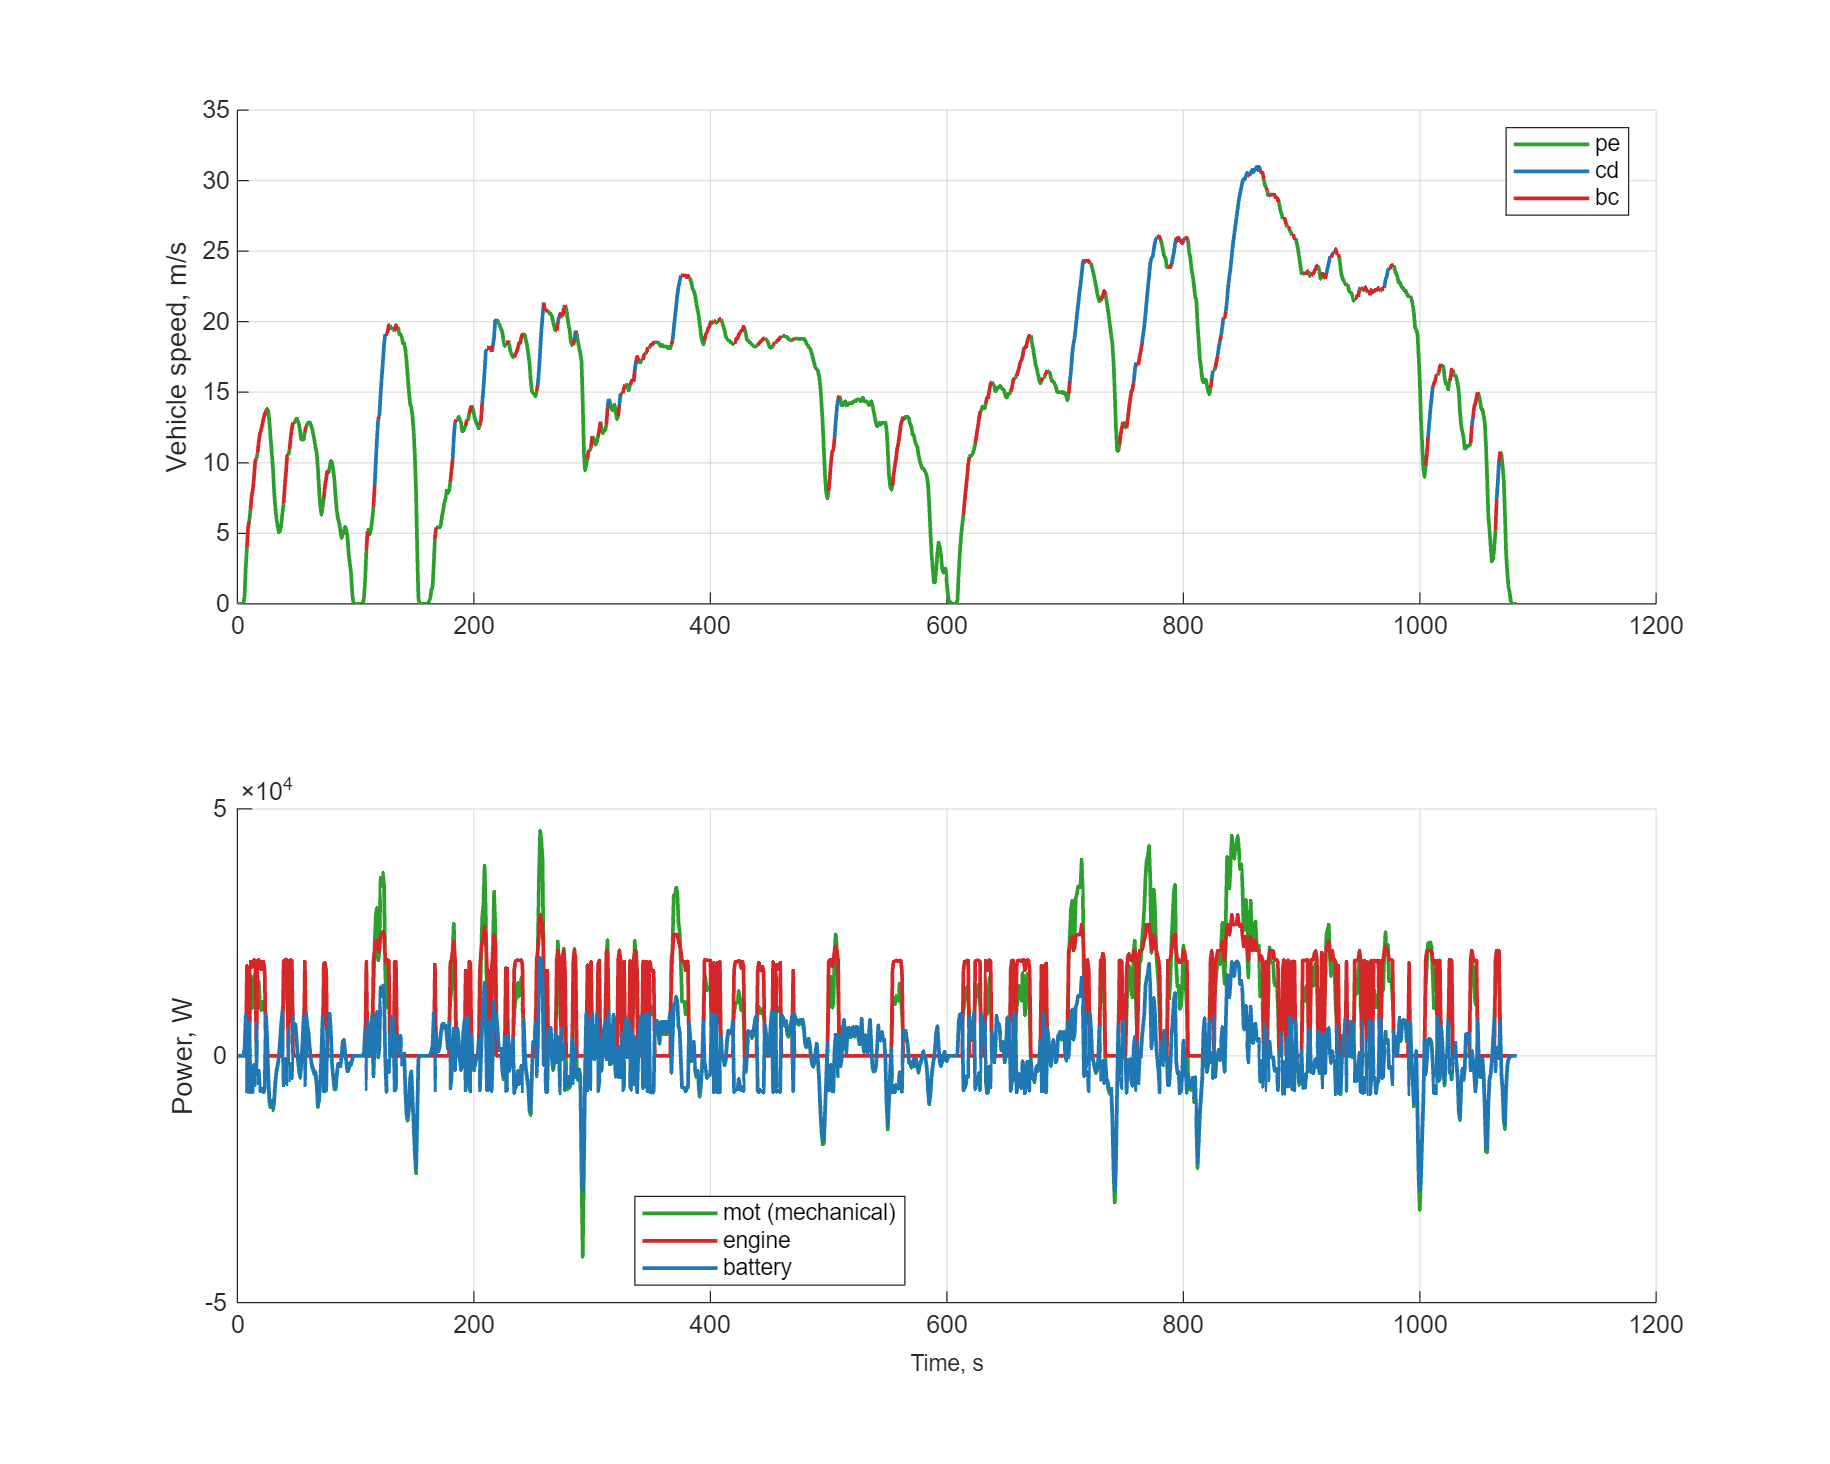

% Compute fuel economy in liters per 100 km
distance = trapz(time, vehSpd) * 1e-3; % Convert meters to km
fuelEconomy = fuelConsumption / veh.eng.fuelDensity / distance * 100;

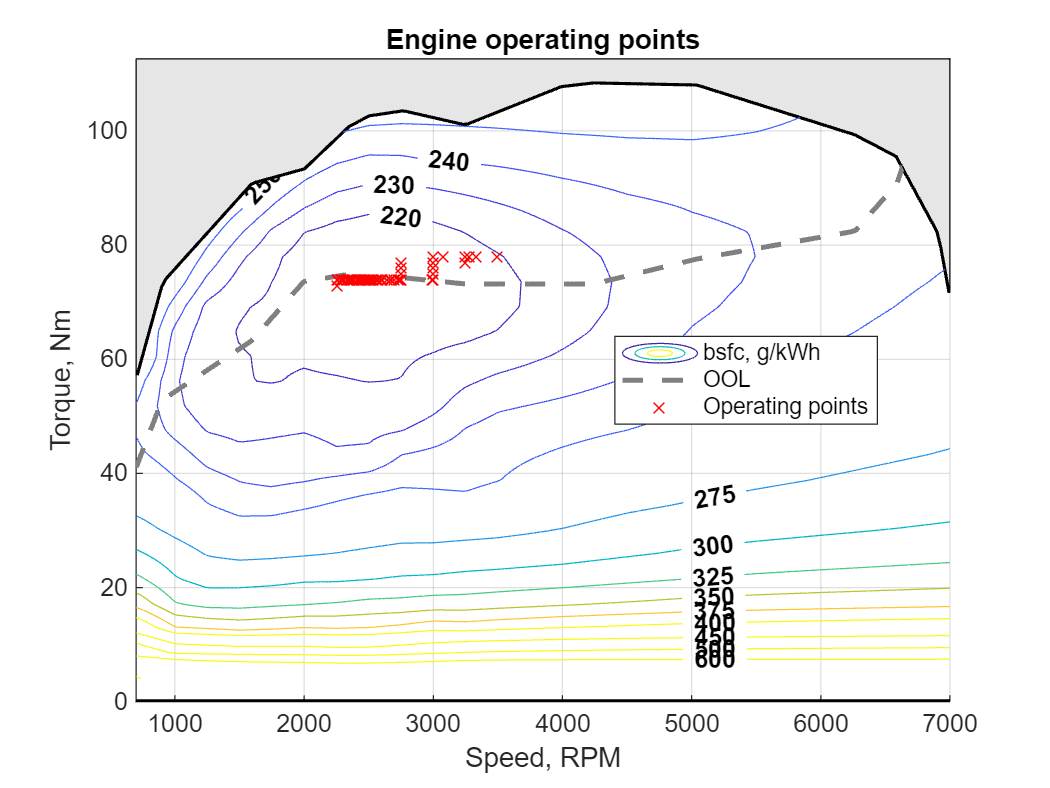


% Print fuel consumption, fuel economy and final SOC
finalSOC = prof.battSOC(end);

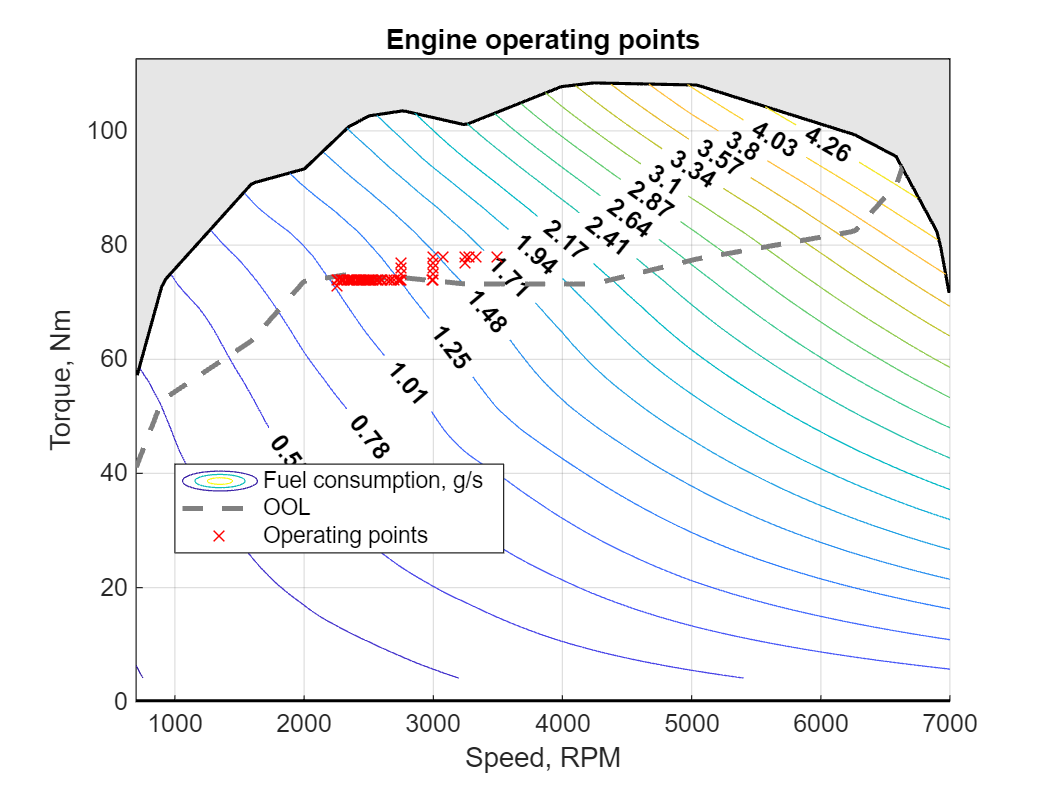

fprintf("Fuel consumption: %.2f kg\n", fuelConsumption);
fprintf("Fuel economy: %.2f l/100km\n", fuelEconomy );
fprintf("Final SOC: %.3f\n", finalSOC );

You can move this code wherever you need.

Finally, use this code to save your results (based on your calibrated equivalence factor)

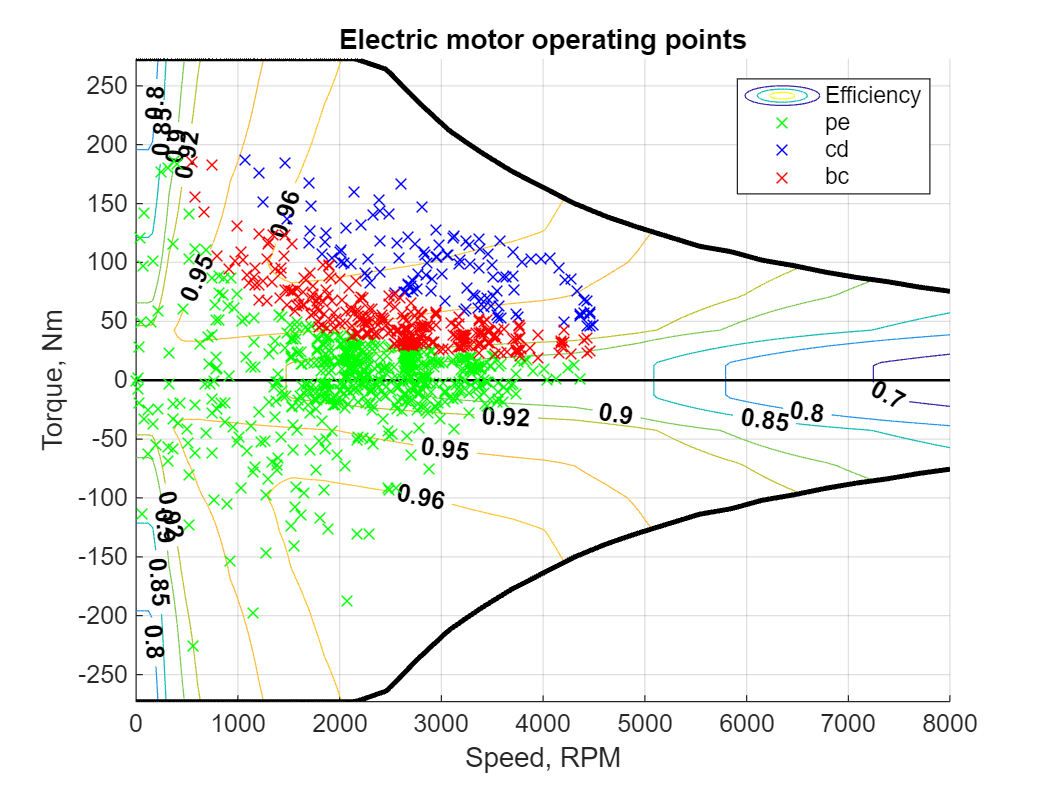

% Store results
save("results.mat", "prof", "stageCost") % "fuelEconomy", "finalSOC", "eqFactor"

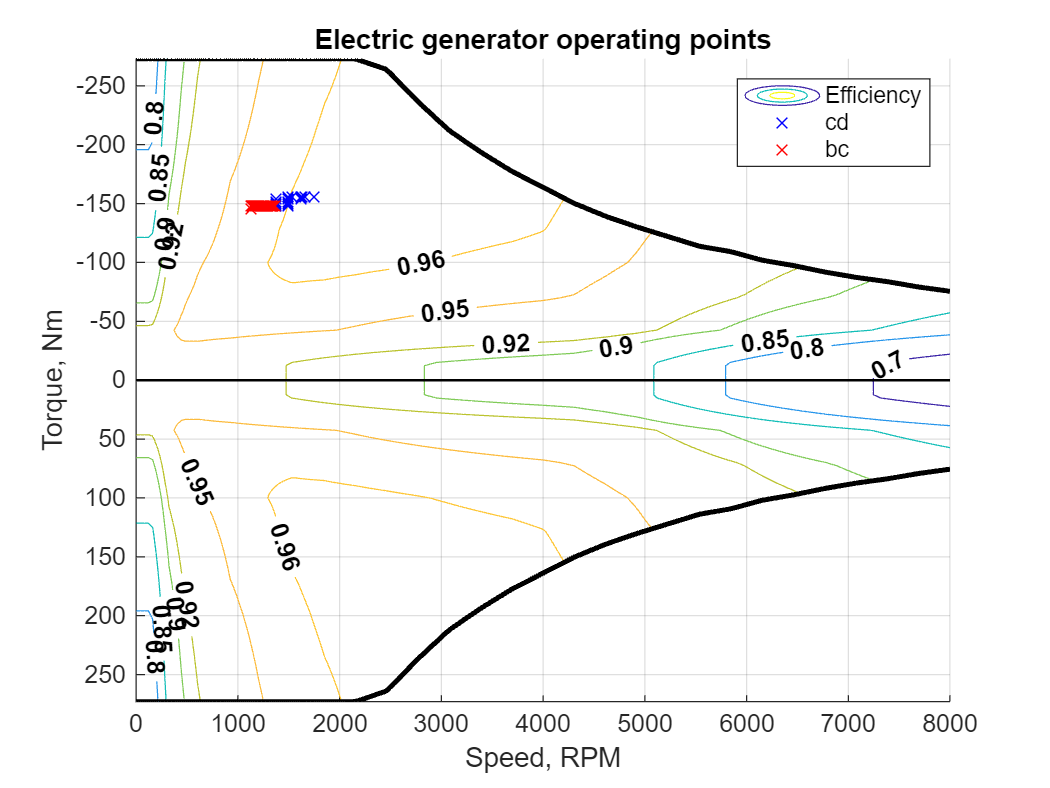


% Display the main Time Profiles (Vehicle speed, SOC, ICE Power, Fuel Consumption)
mainProfiles(prof);


% Display other Time Profiles (Motor Power, ICE Power, Battery Power)
powerProfiles(prof, ["mot_mech", "eng", "batt"]);

% Generate and display the engine 'bsfc' map with power flow based on the exprimental data 
engMapWithPF(veh.eng, prof, 'bsfc');

% Generate and display the engine 'fuel consumption' map with power flow based on the exprimental data 
engMapWithPF(veh.eng, prof, 'fc');

% Generate and display the electrical motor map with power flow based on the experimental data
emMapWithPF(veh.mot, prof, 'mot', 'all');

% Generate and display the electrical generator map with power flow based on the experimental data
emMapWithPF(veh.mot, prof, 'gen', 'all');

- `prof`, `fuelConsumption` , `fuelEconomy`, `finalSOC` are as in Lab 01.

- `eqFactor` is the calibrated equivalence factor.

## Controller analysis

Analyze the behaviour and the performance of the calibrated ECMS controller; support your analysis with relevant plots. You can use the postprocessing functions we provided and/or produce your own plots.

## The ECMS controller

Describe your implementation of the ecms controller, by using code comments and this text section. **You will not get full marks if your function is not documented appropriately.**

In particular:

- Describe all inputs and outputs and why you need them.

- Name/briefly describe any other parameter that you create.

- Clearly explain in plain text how your controller works.

Remember that your ECMS must enforce the condition that the SOC never exceeds the following upper and lower thresholds:

- $\sigma_\mathrm{up} = 0.8$,

-  $\sigma_\mathrm{lo} = 0.4$.

Also, not that this section *must* come at the end of the live script, or your function will not be properly recognized by the preceding part of the script. Local functions, including this one and any other function that you may want to define, must always be defined at the end of your script.


% function [engSpd, engTrq] = ecmsControl(SOC, vehSpd, vehAcc, s, veh)
% 
% MaxTrq = max(veh.eng.maxTrq.Values);
% 
% num_spd_points = 9; % Numero di punti per la velocità (RIGHE)
% num_Trq_points = 10;     % Numero di punti per la coppia (COLONNE)
% 
% engSpd_values = linspace(veh.eng.idleSpd, veh.eng.maxSpd, num_spd_points); % [rad/sec] Values of engine speed
% engSpd_values = [0,engSpd_values];
% num_spd_points = length(engSpd_values);
% engTrq_values = linspace(0, MaxTrq, num_Trq_points); 
% 
% % Matrici
% eqConsumption = NaN(length(engSpd_values), length(engTrq_values));
% 
% for i = 1:length(engSpd_values)
%     for j = 1:length(engTrq_values)
%         engSpd = engSpd_values(i);
%         engTrq = engTrq_values(j);
% 
%         % Chiamata al modello
%         [SOC_next, stageCost, unfeas] = hev_model(SOC, [engSpd; engTrq], [vehSpd; vehAcc], veh);
% 
%         socUnfeas = (SOC_next > 0.8) || (SOC_next < 0.4);
% 
%         if unfeas || socUnfeas
%             eqConsumption(i,j) = 10e6; % unfease
%             continue
%         end
% 
%         % Calcolo SOC_dot
%         SOC_dot = (SOC_next(1) - SOC(1)) / veh.dt;
% 
%         % Costo equivalente
%         eqConsumption(i,j) = stageCost - s * (veh.batt.nomEnergy * 3600 / (veh.eng.fuelLHV / 1000)) * SOC_dot;
%     end
% end
% 
% % Trova l'indice del minimo
% [~, linear_index] = min(eqConsumption(:));
% [row_idx, col_idx] = ind2sub(size(eqConsumption), linear_index);
% 
% 
% engSpd = engSpd_values(row_idx);
% engTrq = engTrq_values(col_idx);
% 
% end


Simulation

function psi = run_simulation(eqFactor, time, vehSpd, vehAcc, veh)
SOC(1) = 0.6;
for n = 1:length(time)
    [engSpd(n), engTrq(n)] = ecmsControl(SOC(n), vehSpd(n), vehAcc(n), eqFactor, veh);
    [SOC(n+1), stageCost(n), unfeas(n), prof(n)] = ...
        hev_model(SOC(n), [engSpd(n), engTrq(n)], [vehSpd(n), vehAcc(n)], veh);
end
psi = SOC(end)-SOC(1);
end


function [engSpd, engTrq] = ecmsControl(SOC, vehSpd, vehAcc, s, veh)

engSpd_set = [0, veh.eng.idleSpd:veh.eng.maxSpd];

MaxTrq = max(veh.eng.maxTrq.Values);
engTrq_set = 0:MaxTrq;

[engSpd_grid, engTrq_grid] = ndgrid(engSpd_set, engTrq_set);

[SOC_next, stageCost, unfeas] = ...
    hev_cell_model({SOC}, {engSpd_grid, engTrq_grid}, {vehSpd, vehAcc}, veh);

SOC_dot = (SOC_next{1} - SOC) / veh.dt;

socUnfeas = (SOC_next{1} > 0.8) | (SOC_next{1} < 0.4);

eqConsumption = stageCost - s * (veh.batt.nomEnergy * 3600 / (veh.eng.fuelLHV / 1000)) * SOC_dot + unfeas*1e5 + socUnfeas*1e5;

% Trova l'indice del minimo
[~, linear_index] = min(eqConsumption(:));
[row_idx, col_idx] = ind2sub(size(eqConsumption), linear_index);


engSpd = engSpd_grid(row_idx, col_idx);
engTrq = engTrq_grid(row_idx, col_idx);
end